# Assignment 11

# **Extended Kalman filter for navigation and tracking** 

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

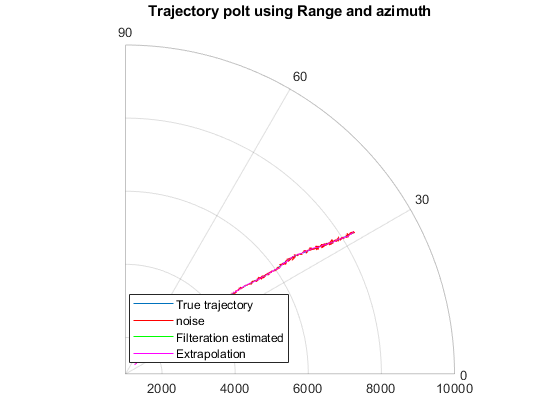

close all;
clear;

m=1;    %Extrapolation steps
N=500;  %Number of points
NE=N-m; %Number of points for the extrapolation error
Mm=500; %Number of runs

%Kalman errors initialization
ErrD=zeros(Mm,N);          %D true estimation error
ErrDE=zeros(Mm,NE);        %D-extrapolated true estimation error
Errbeta=zeros(Mm,N);       %beta true estimation error
ErrbetaE=zeros(Mm,NE);     %beta-extrapolated true estimation error

for M=1:Mm

    X=zeros(1,N);           %X-position
    Y=zeros(1,N);           %Y-position
    X(1)=1000;     %X initial value
    Y(1)=1000;     %Y initial value
    VX=zeros(1,N);          %X-Velocity
    VY=zeros(1,N);          %Y-Velocity
    VX(1)=10;     %X initial velocity
    VY(1)=10;     %Y initial velocity
    T=1;        %Time step
    
    sigma_a=0.3;      %Acceleration noise standard deviation
    
    normaldist=makedist('Normal',0,sigma_a);
    ax=random(normaldist,N,1);            %X-Acceleration noise
    
    normaldist=makedist('Normal',0,sigma_a);
    ay=random(normaldist,N,1);            %Y-Acceleration noise
    
    
    sigma_d=50;               %Range measurements noise standard deviation
    sigma_beta=0.004;          %Azimuth measurements noise standard deviation

    D=zeros(1,N);             %Range
    beta=zeros(1,N);          %Azimuth
    D(1)=sqrt(X(1)^2+Y(1)^2); %Range initial value
    beta(1)=atan2(X(1),Y(1));  %Azimuth initial value

    normaldist=makedist('Normal',0,sigma_d);
    eta_d=random(normaldist,N,1);            %Range measurements noise vector

    normaldist=makedist('Normal',0,sigma_beta);
    eta_b=random(normaldist,N,1);            %Azimuth measurements noise vector
    D_m=D;                                   %Range measurements
    beta_m=beta;                             %Azimuth measurements

    D_m(1)=D(1)+eta_d(1);                    %Range measurements initialization
    beta_m(1)=beta(1)+eta_b(1);              %Azimuth measurements initialization

    %Vectors generation
    for i=2:N
        X(i)=X(i-1)+VX(i-1)*T+0.5*ax(i-1)*T^2;        %X vector generation
        VX(i)=VX(i-1)+ax(i-1)*T;                    %X Velocity generation
        Y(i)=Y(i-1)+VY(i-1)*T+0.5*ay(i-1)*T^2;        %Y vector generation
        VY(i)=VY(i-1)+ay(i-1)*T;                    %Y Velocity generation        
        D(i)=sqrt(X(i)^2+Y(i)^2);     %Range vector generation
        beta(i)=atan2(X(i),Y(i));      %Azimuth vector generation

        D_m(i)=D(i)+eta_d(i);         %Range measurements vector generation
        beta_m(i)=beta(i)+eta_b(i);   %Azimuth measurements vector generation
    end

    Z=[D_m;beta_m];                %Cartesian measurments

    %Kalman filter parameters initialization
    Xi=[D_m(1)*sin(beta_m(1));0;D_m(1)*cos(beta_m(1));0];   %State vector
    P=(10^10)*eye(4);         %P matrix

    %state space matrices
    phi=[1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];

    G=[0.5*T^2 0;T 0;0 0.5*T^2;0 T];
    
    Q=G*G'*sigma_a^2;
    
    xi=Xi(1);
    yi=Xi(3);
    x2y2=xi^2+yi^2;
    h=[sqrt(xi^2+yi^2);atan2(xi,yi)];
    hprime=[xi/sqrt(x2y2) 0 yi/sqrt(x2y2) 0; yi/x2y2 0 -xi/x2y2 0];

    R=[sigma_d^2 0;0 sigma_beta^2];     %Error covariance matrix
    K=P*hprime'/(hprime*P*hprime'+R);   %initial kalman gain

    Di=zeros(N,1);       %filtered Range
    betai=zeros(N,1);    %filtered Azimuth

    DiE=zeros(N,1);     %Extrapolated Range
    betaiE=zeros(N,1);  %Extrapolated Azimuth

    Ki=zeros(1,N);      %array of K(1,1)

    %Kalman filter
    for i=1:N
        Xi=phi*Xi;
        P=phi*P*phi'+Q;
        
        xi=Xi(1);
        yi=Xi(3);
        x2y2=xi^2+yi^2;
        h=[sqrt(xi^2+yi^2);atan2(xi,yi)];
        hprime=[xi/sqrt(x2y2) 0 yi/sqrt(x2y2) 0; yi/x2y2 0 -xi/x2y2 0]; 
        
        Xi=Xi+K*(Z(:,i)-h);

        K=P*hprime'/(hprime*P*hprime'+R);
        P=(eye(4)-K*hprime)*P;
        XiE=Xi;

        for mm=m
            XiE=phi*XiE;     %Extrapolated state vector
        end


        %Range and azimuth estimation (filtered and extrapolated)
        Di(i)=sqrt(Xi(1)^2+Xi(3)^2);
        betai(i)=atan2(Xi(1),Xi(3));
        DiE(i)=sqrt(XiE(1)^2+XiE(3)^2);
        betaiE(i)=atan2(XiE(1),XiE(3));


        %True estimation error calculation
        ErrD(M,i)=(Di(i)-D(i))^2;
        Errbeta(M,i)=(betai(i)-beta(i))^2;

        %Extrapolation error calculation
        if i<N
            ErrDE(M,i)=(DiE(i)-D(i+m))^2;
            ErrbetaE(M,i)=(betaiE(i)-beta(i+m))^2;
        end
    end
end

%Trajectory plotting for visualization
polarplot(beta,D,beta_m,D_m,'r',betai,Di,'g',betaiE,DiE,'m')
rlim([1000 10000])
thetalim([0 90])
%{
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
%}
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},...
    'location','southwest')

**Comment:**

In this figure above we can see the true trajectory, the measurements, the filtered and the extrapolated states for  range and azimuth in polar coordinates. Both the estimation and extrapolation are converging to the true trajectory and very close to it. this gives a good indecation on how effective is our filteration. 

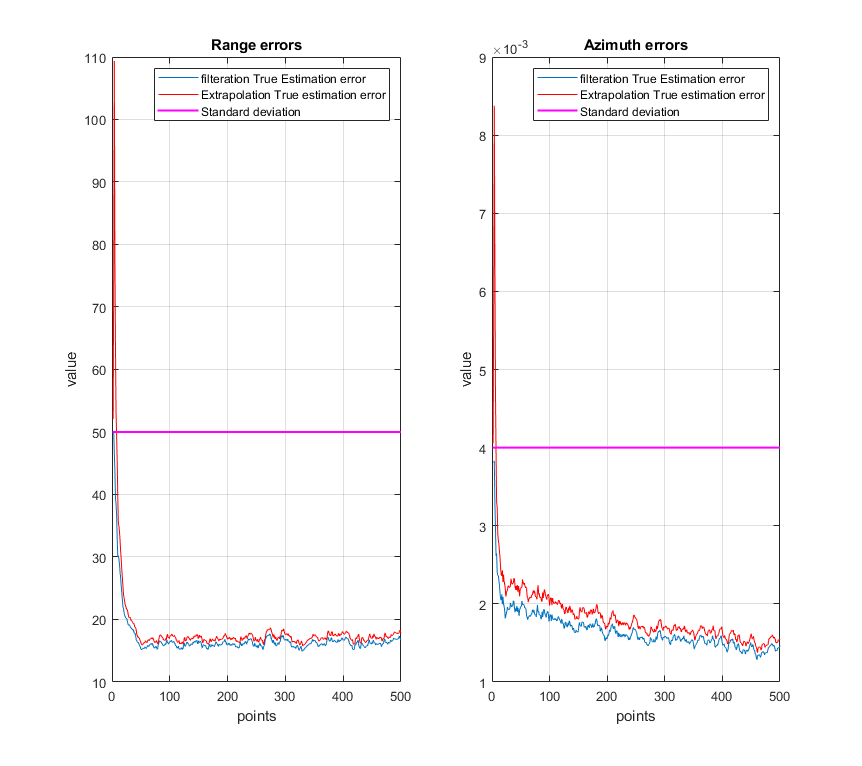

%plotting errors
figure
subplot(1,2,1)
plotErr(ErrD,ErrDE,sigma_d*ones(1,N),'Range')
subplot(1,2,2)
plotErr(Errbeta,ErrbetaE,sigma_beta*ones(1,N),'Azimuth')

**Comment:**

In the figure above, both filteration and extrapolation estimation errors are vey small ccompared to the standarad deviation of the error in range measurments. The filteration error settles around a value of ~16 while the extrapolation is slightly higher aproaching a value of ~17, which is more than great in both cases comapred to the value of the standarad deviation in the measurment error. This also applies to the results of errors of estimations in filteration and exptrapolation for the azimuth . As, filteration error settles on a value of ~0.0014*10^-3 while the extrapolation is slightly higher with a value of ~0.0015*10^-3 compared to the 0.004 error im azimuth measurments. This gives an indication about the performance of the EKF

# Learning Log: 

In this assignment we develop a tracking filter of a moving object when measurements and motion model are in different coordinate using nonlinear model (Extended Kalman filter), generally using linear models to estimate nonlinear application have its limitations that if not applied carefully the system can't be trusted (linearization limitations), using nonlinear model can provide better estimations in such cases. Eventually we summarized what we learnt in the following:

- Understanding the data (or the problem ) you are dealing with is the key to choosing the most convenient estimation method. For example understanding the relation between variables can decide the type of model you are using for estimation (liner or nonlinear).

- Applying Extended Kalman filter with nonlinear applications is more convenient and gives better approximation with less susceptibility to divergence due to the linearization limits in linear modes.

- we applied EKF to the same conditions we had in Assignment number 10 to compare the results. Shown below is using this EKF with the previous assignment conditions.

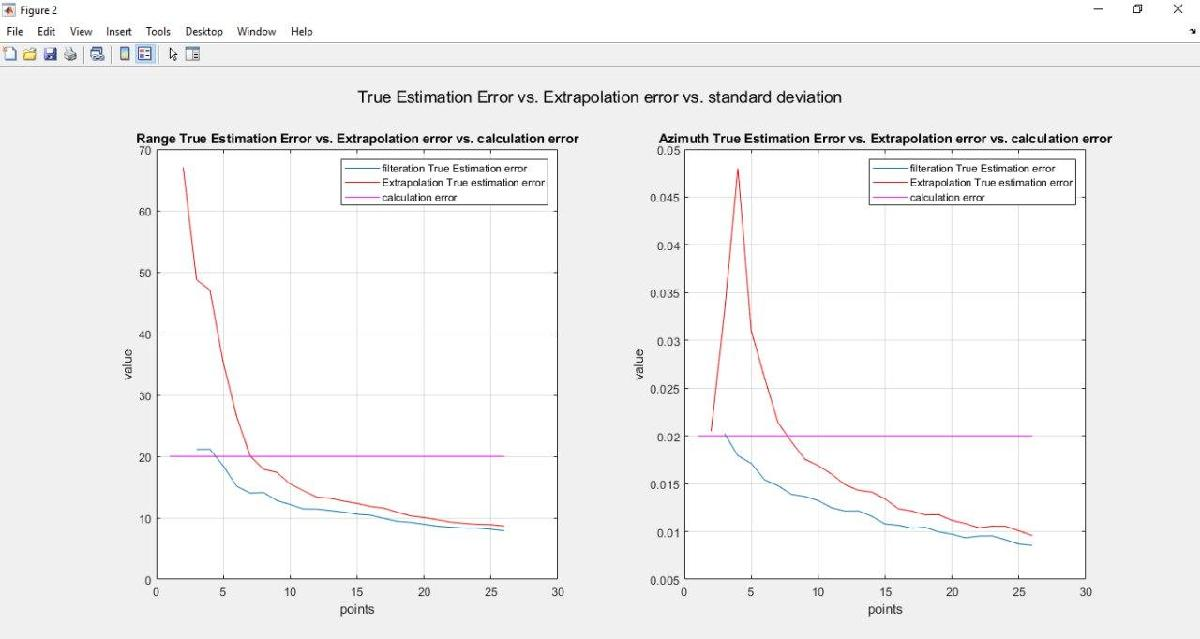

While below is the results of Assignment 10

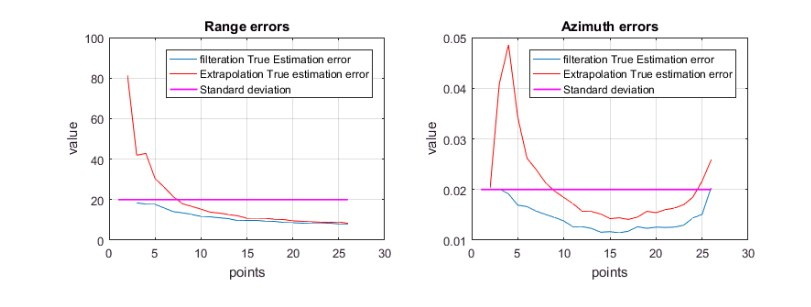

Tn this graph, we can see that the EKF gave better approximation for the Azimuth (the values didn't start to diverge as the object started to get closer to the observer. ) opposite to what we got in assignment 10 (applying linearization)